# Procesamiento de datos (N PB UDH)

clear all;clc;close all;
opts = delimitedTextImportOptions("NumVariables", 24);
% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";
% Specify column names and types
opts.VariableNames = ["Área", "Longitud eje mayor", "Longitud eje menor", "Área convexa","Circularidad", "Perímetro", "Distancia mínima entre núcleos", "Varianza área","Varianza área convexa","Varianza circularidad","Varianza perímetro","Varianza longitud eje mayor","Ratio medio distancia ejes","Porcentaje de núcleos","Varianza de la distancia del eje menor","Compactabilidad de núcleos","Distancia media entre núcleos","Varianza distancia entre núcleos","Varianza del ratio de distancia ejes","Contraste","Correlación", "Homogenidad","Energía","Tipo de cáncer"];
opts.VariableTypes = ["double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","categorical"];
% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";
A = struct2cell(load("0_N.mat"));
A = A{1,1};
B = struct2cell(load("1_PB.mat"));
B = B{1,1};
C = struct2cell(load("2_UDH.mat"));
C = C{1,1};
taula = [A; B; C];

[UniqueData,Repeatedpoints]=repeated_data(taula);%cambiar nombre de la función

nRepeatedPoints =      0


Uniquedata = 242×24 table
       Infomean1           Infomean2           Infomean3           Infomean4            Infomean5           Infomean6             Infomean7             Infomean8           Infomean9            Infomean10           Infomean11          Infomean12          Infomean13          Infomean14           Infomean15          Infomean16           Infomean17            Infomean18           Infomean19           Infomean20           Infomean21           Infomean22           Infomean23        Var24
    ________________    ________________    <

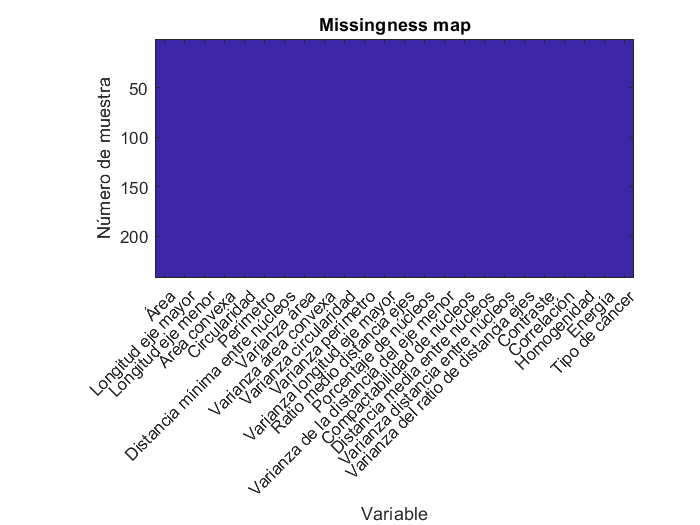

Nombres = opts.VariableNames;
Nombres;
PreprocessedDdata = processed(UniqueData);
imagesc(ismissing(PreprocessedDdata,{'' '.' 'NA' NaN -99}))
xticks(1:length(Nombres));
xticklabels(Nombres);
xtickangle(45)
title('Missingness map');
xlabel('Variable');
ylabel('Número de muestra')

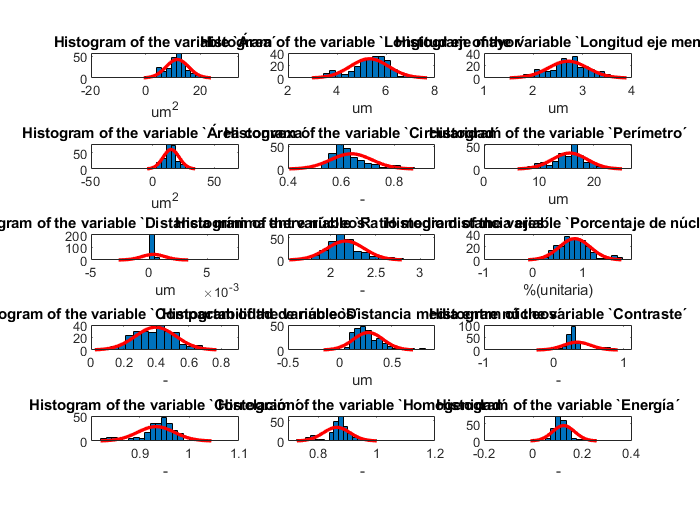


a=[1:7,13,14,16,17,20:23];
b=[24];
c=b;
units= ["um^2","um","um","um^2","-","um","um","-v","-v","-v","-v","-v","-","%(unitaria)","-v","-","um","-v","-v","-","-","-","-"];
[dataN,response_var,independent_vars,categorical_vars] =inconsistent_data(PreprocessedDdata,a,b,c);

for i=1:length(a)
    subplot(5,3,i)
    h = histfit(independent_vars(:,i));
    maximo(i) = max(h(2).XData);
    minimo(i) = min(h(2).XData);
    if minimo(i)<0
        minimo(i) = 0;
    end
    %histfit(independent_vars(:,i))
    title(strcat('Histogram of the variable `',Nombres{a(i)},'´'));
    xlabel(units{a(i)});
end

l=1;

for p=1:height(dataN)
    if independent_vars(p,1:width(independent_vars))>minimo(1:width(independent_vars)) & independent_vars(p,1:width(independent_vars))<maximo(1:width(independent_vars))
        dataN1(l,:)=(dataN(p,:));
        l= l+1;
    end
end
independent_vars1 =  table2array(dataN1(:,a));
% independent_vars1 = table2array(independent_vars1);
for i=1:15
    fprintf('Mean value for variable %s is %.2f\n', Nombres{a(i)},mean(independent_vars1(:,i)));%FALTA TRADUCIR
    fprintf('Median for variable %s is %.2f\n', Nombres{a(i)},median(independent_vars1(:,i)));
    fprintf('Mode for variable %s is %.2f\n', Nombres{a(i)},mode(round(independent_vars1(:,i),1)));
    fprintf('Max. value for variable %s is %.2f\n', Nombres{a(i)},max(independent_vars1(:,i)));
    fprintf('Min. value for variable %s is %.2f\n', Nombres{a(i)},min(independent_vars1(:,i)));
    fprintf('Standard deviation for variable %s is %.2f\n \n', Nombres{a(i)},std(independent_vars1(:,i)));
end

Mean value for variable Área is 11.56


Median for variable Área is 11.42


Mode for variable Área is 10.80


Max. value for variable Área is 21.05


Min. value for variable Área is 4.53


Standard deviation for variable Área is 3.53
 


Mean value for variable Longitud eje mayor is 5.34


Median for variable Longitud eje mayor is 5.43


Mode for variable Longitud eje mayor is 5.40


Max. value for variable Longitud eje mayor is 7.05


Min. value for variable Longitud eje mayor is 3.49


Standard deviation for variable Longitud eje mayor is 0.74
 


Mean value for variable Longitud eje menor is 2.71


Median for variable Longitud eje menor is 2.72


Mode for variable Longitud eje menor is 2.90


Max. value for variable Longitud eje menor is 3.56


Min. value for variable Longitud eje menor is 1.85


Standard deviation for variable Longitud eje menor is 0.38
 


Mean value for variable Área convexa is 14.77


Median for variable Área convexa is 14.60


Mode for variable Área convexa is 13.10


Max. value for variable Área convexa is 28.57


Min. value for variable Área convexa is 5.56


Standard deviation for variable Área convexa is 4.78
 


Mean value for variable Circularidad is 0.63


Median for variable Circularidad is 0.62


Mode for variable Circularidad is 0.60


Max. value for variable Circularidad is 0.87


Min. value for variable Circularidad is 0.51


Standard deviation for variable Circularidad is 0.07
 


Mean value for variable Perímetro is 15.68


Median for variable Perímetro is 16.08


Mode for variable Perímetro is 14.50


Max. value for variable Perímetro is 24.60


Min. value for variable Perímetro is 8.92


Standard deviation for variable Perímetro is 2.93
 


Mean value for variable Distancia mínima entre núcleos is 0.00


Median for variable Distancia mínima entre núcleos is 0.00


Mode for variable Distancia mínima entre núcleos is 0.00


Max. value for variable Distancia mínima entre núcleos is 0.00


Min. value for variable Distancia mínima entre núcleos is 0.00


Standard deviation for variable Distancia mínima entre núcleos is 0.00
 


Mean value for variable Ratio medio distancia ejes is 2.17


Median for variable Ratio medio distancia ejes is 2.15


Mode for variable Ratio medio distancia ejes is 2.10


Max. value for variable Ratio medio distancia ejes is 2.79


Min. value for variable Ratio medio distancia ejes is 1.66


Standard deviation for variable Ratio medio distancia ejes is 0.20
 


Mean value for variable Porcentaje de núcleos is 0.84


Median for variable Porcentaje de núcleos is 0.82


Mode for variable Porcentaje de núcleos is 0.70


Max. value for variable Porcentaje de núcleos is 1.75


Min. value for variable Porcentaje de núcleos is 0.21


Standard deviation for variable Porcentaje de núcleos is 0.29
 


Mean value for variable Compactabilidad de núcleos is 0.39


Median for variable Compactabilidad de núcleos is 0.39


Mode for variable Compactabilidad de núcleos is 0.40


Max. value for variable Compactabilidad de núcleos is 0.65


Min. value for variable Compactabilidad de núcleos is 0.13


Standard deviation for variable Compactabilidad de núcleos is 0.11
 


Mean value for variable Distancia media entre núcleos is 0.25


Median for variable Distancia media entre núcleos is 0.23


Mode for variable Distancia media entre núcleos is 0.20


Max. value for variable Distancia media entre núcleos is 0.70


Min. value for variable Distancia media entre núcleos is 0.07


Standard deviation for variable Distancia media entre núcleos is 0.12
 


Mean value for variable Contraste is 0.32


Median for variable Contraste is 0.27


Mode for variable Contraste is 0.30


Max. value for variable Contraste is 0.91


Min. value for variable Contraste is 0.14


Standard deviation for variable Contraste is 0.17
 


Mean value for variable Correlación is 0.93


Median for variable Correlación is 0.94


Mode for variable Correlación is 0.90


Max. value for variable Correlación is 0.98


Min. value for variable Correlación is 0.82


Standard deviation for variable Correlación is 0.03
 


Mean value for variable Homogenidad is 0.86


Median for variable Homogenidad is 0.87


Mode for variable Homogenidad is 0.90


Max. value for variable Homogenidad is 0.94


Min. value for variable Homogenidad is 0.74


Standard deviation for variable Homogenidad is 0.04
 


Mean value for variable Energía is 0.12


Median for variable Energía is 0.11


Mode for variable Energía is 0.10


Max. value for variable Energía is 0.25


Min. value for variable Energía is 0.06


Standard deviation for variable Energía is 0.03
 


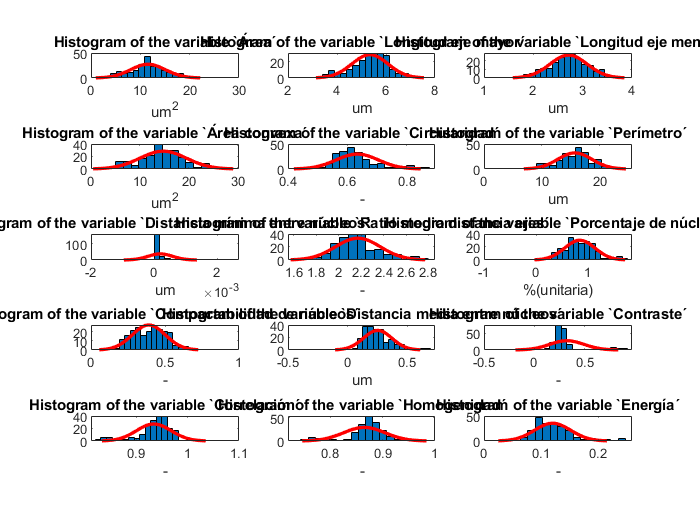

for i=1:length(a)
    subplot(5,3,i)
    h = histfit(independent_vars1(:,i));
    histfit(independent_vars1(:,i))
    title(strcat('Histogram of the variable `',Nombres{a(i)},'´'));
    xlabel(units{a(i)});
end

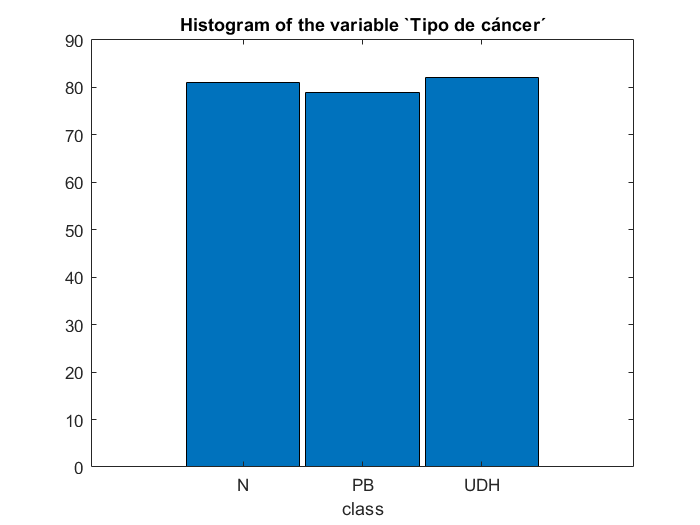

figure ()
%corrplot(dataN1(:,1:23));
A=categorical_vars(:,1);
B=removecats(A);
hist(categorical_vars(:,1),(categories(B)))
title(strcat('Histogram of the variable `',Nombres{b(1)},'´'));
xlabel('class');

dataN2=(dataN1);
%dataN2=table2array(dataN2);
for i=1:23
    dataN2(:,i)=array2table(rescale(table2array(dataN1(:,i))));
end

dataN3=[]


dataN3 =

     []



dataN4=[]


dataN4 =

     []



dataN5=[]


dataN5 =

     []




f=24;
a1=1;
b1=1;
c1=1;

[m1,n1]= size(dataN1);
for i = 1:m1
    if table2array(dataN1(i,f)) == "N"
        dataN3 = [dataN3 i];
        a1=a1+1;
    end
    if  table2array(dataN1(i,f)) == "PB"
        dataN4 = [dataN4 i];
        b1=b1+1;
    end
    if table2array(dataN1(i,f)) == "UDH"
        dataN5 = [dataN5 i];
        c1=c1+1;
    end
end

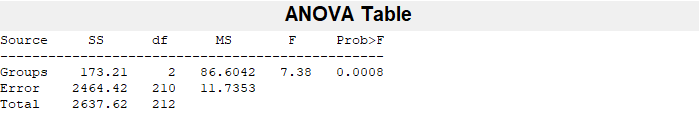

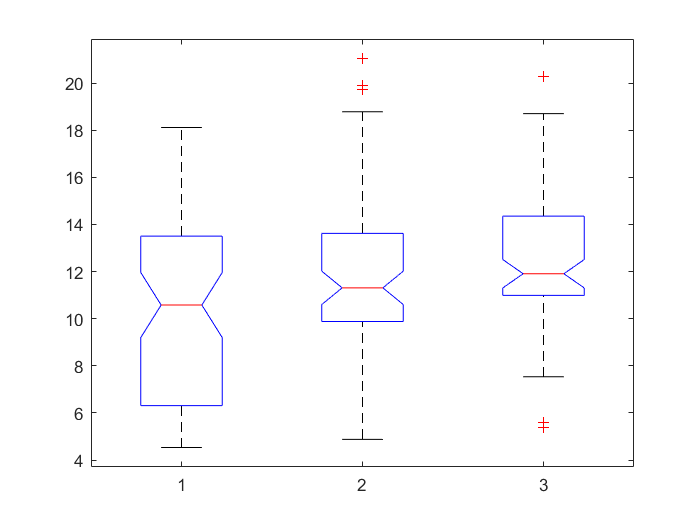

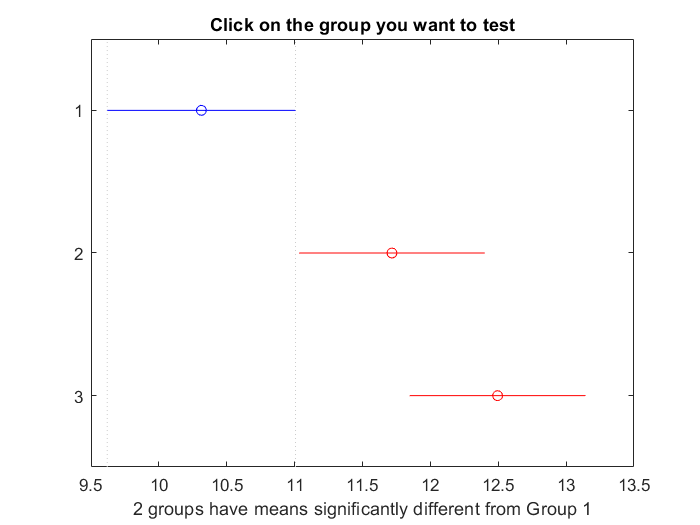

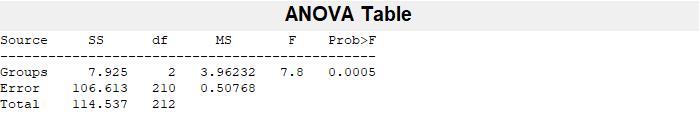

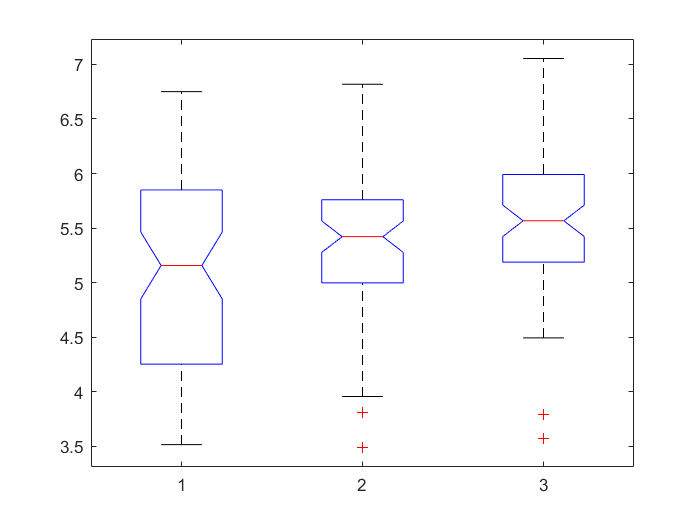

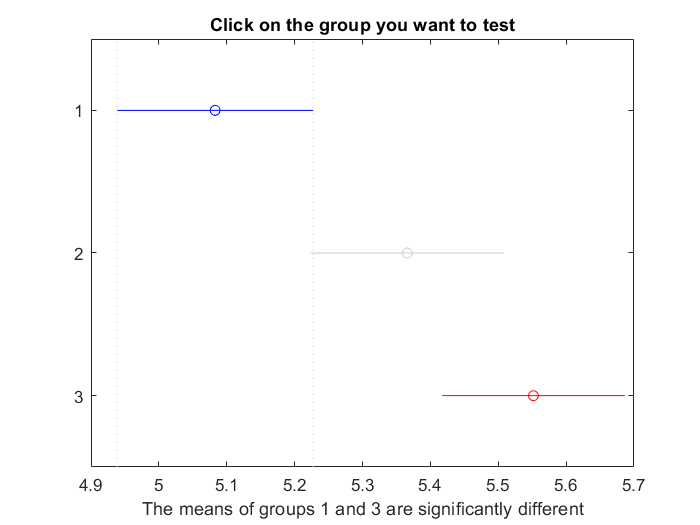

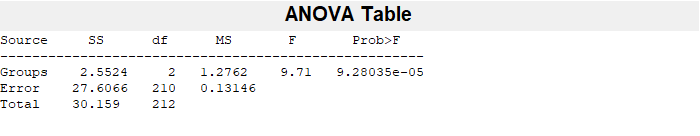

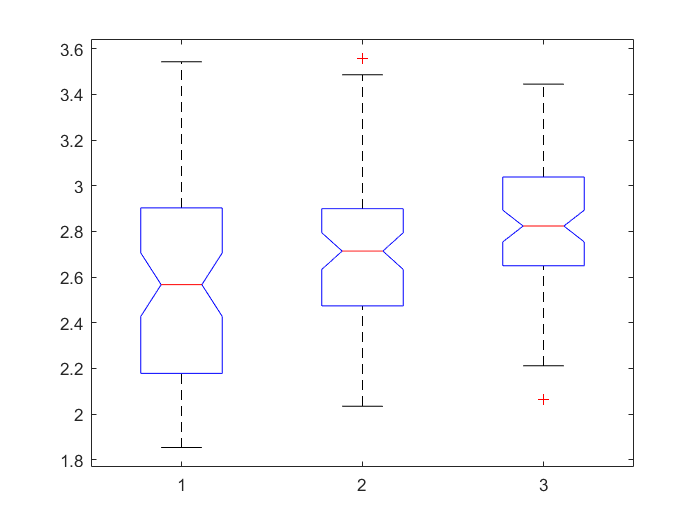

taula_N = dataN1(transpose(dataN3),:); 
taula_PB = dataN1(transpose(dataN4),:);
taula_UDH = dataN1(transpose(dataN5),:);
DataAnova = [taula_N(:,1:23); taula_PB(:,1:23); taula_UDH(:,1:23)];
DataAnova = rows2vars(DataAnova);
DataAnova(:,1)=[];
DataAnova = table2array(DataAnova);
% GroupsAnova = [rows2vars(taula_N(:,24)) rows2vars(taula_PB(:,24)) rows2vars(taula_UDH(:,24)) rows2vars(taula_FEA(:,24)) rows2vars(taula_ADH(:,24))  rows2vars(taula_DCIS(:,24)) rows2vars(taula_IC(:,24))];
optA=rows2vars(taula_N(:,24));
optB=rows2vars((taula_PB(:,24)));
optC=rows2vars((taula_UDH(:,24)));
A1=ones(1,width(optA)-1);
B1=2.*ones(1,width(optB)-1);
C1=3.*ones(1,width(optC)-1);
GroupsAnova=[A1 B1 C1];
for a = 1:23
    [p1(a),ANOVATAB,stats] =anova1(DataAnova(a,:),GroupsAnova);
    p2(:,:,a) = multcompare(stats);
end

idx = fscmrmr(dataN2,"Tipo de cáncer");

data_corr = dataN2;
data1 = dataN2;
data_todo = dataN2;
data_corr(:, [1,2,3,4,6,8,10,12,13,22]) = [];
data1(:, [1,2,4,6,8,12,13,17,18,22]) = [];
data_todo(:,[1,2,3,4,6,13]) = [];
k = 5;
cvpt = cvpartition(data_corr.("Tipo de cáncer"),"KFold",k);
cvpt1 = cvpartition(data1.("Tipo de cáncer"),"KFold",k);
cvpt2 = cvpartition(data_todo.("Tipo de cáncer"),"KFold",k);

## knn


mdl = fitcknn(data_corr, "Tipo de cáncer","NumNeighbors",4,"CVPartition",cvpt, 'DistanceWeight', 'inverse');
mdlLoss = kfoldLoss(mdl) %This row will print the mean Loss value. 

mdlLoss =    0.413145539906103


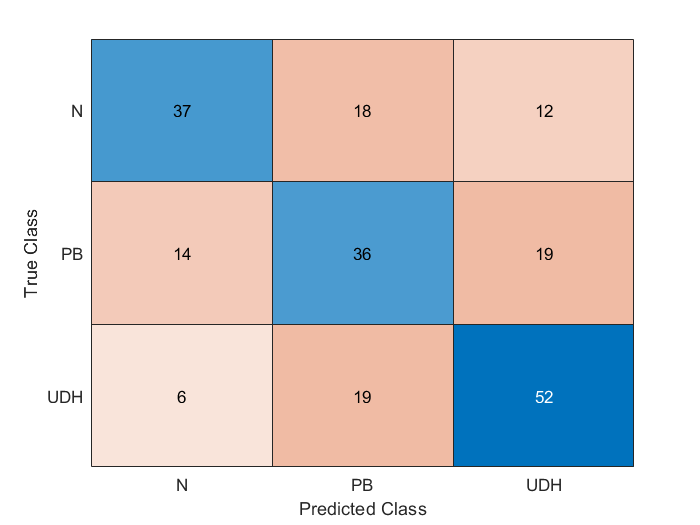

mdlLoss = kfoldLoss(mdl, 'Mode', 'Individual'); %This row will compute the Loss for each Cross-Validation fold. This is interesting for the final comparisons. 
[yFit,sFit] = kfoldPredict(mdl);
confusionchart(data_corr.("Tipo de cáncer"),yFit)


mdl = fitcknn(data_todo, "Tipo de cáncer","NumNeighbors",4,"CVPartition",cvpt, 'DistanceWeight', 'inverse');
mdlLoss = kfoldLoss(mdl) %This row will print the mean Loss value. 

mdlLoss =    0.431924882629107


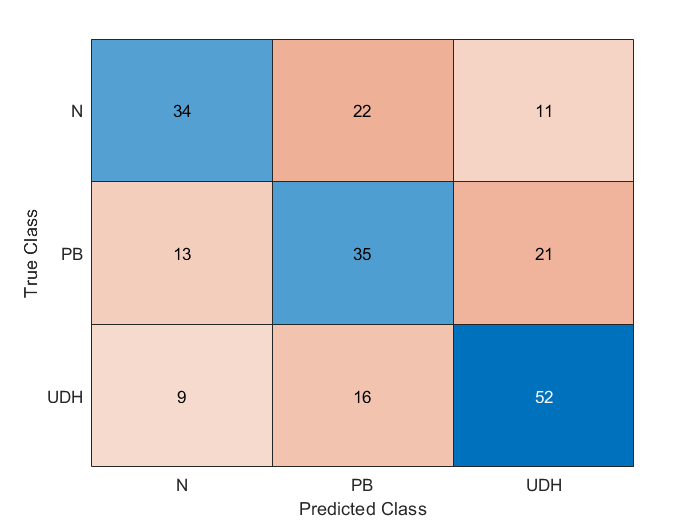

mdlLoss = kfoldLoss(mdl, 'Mode', 'Individual'); %This row will compute the Loss for each Cross-Validation fold. This is interesting for the final comparisons. 
[yFit,sFit] = kfoldPredict(mdl);
confusionchart(data_corr.("Tipo de cáncer"),yFit)

## Classification trees NO

mdlTree = fitctree(data_corr, "Tipo de cáncer","CVPartition",cvpt);
mdlTreeLoss = kfoldLoss(mdlTree)

mdlTreeLoss =    0.507042253521126


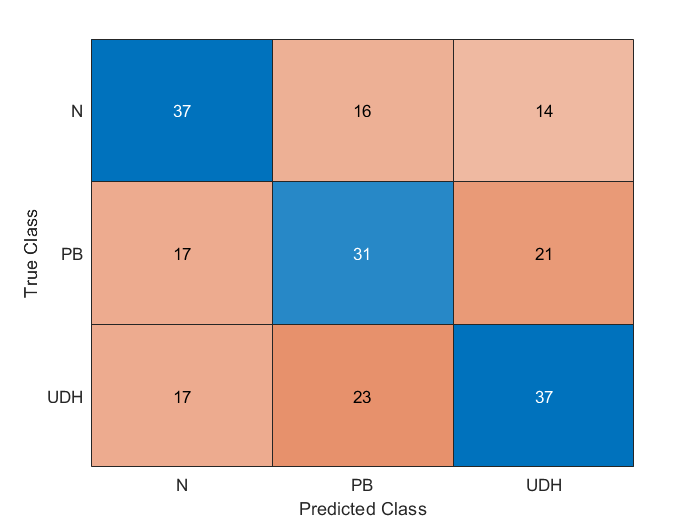

mdlTreeLoss = kfoldLoss(mdlTree, 'Mode', 'Individual');
[yFit,sFit] = kfoldPredict(mdlTree);
confusionchart(data_corr.("Tipo de cáncer"),yFit)

## Naive Bayes NO

mdlNB = fitcnb(data_corr, "Tipo de cáncer","CVPartition",cvpt);
mdlNBLoss = kfoldLoss(mdlNB)

mdlNBLoss =    0.502347417840375


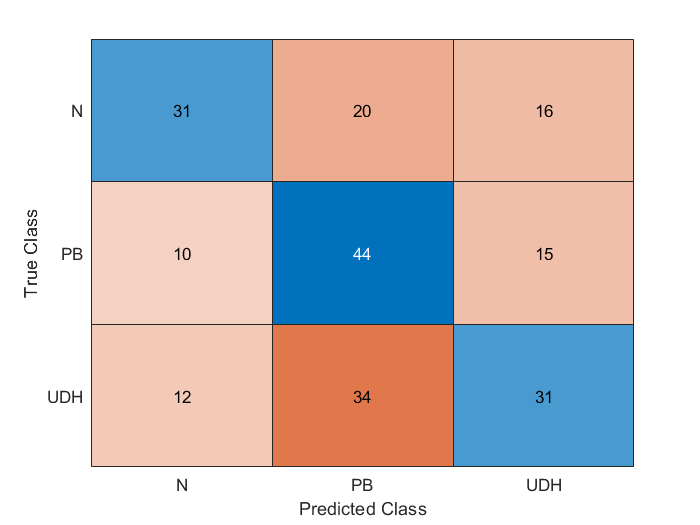

mdlNBLoss = kfoldLoss(mdlNB, 'Mode', 'Individual');
[yFit,sFit] = kfoldPredict(mdlNB);
confusionchart(data_corr.("Tipo de cáncer"),yFit)

## Discriminant Analysis

opt = struct("CVPartition",cvpt);
%mdlDisAn_opt = fitcdiscr(data_corr, "Tipo de cáncer","OptimizeHyperparameters","auto","HyperparameterOptimizationOptions",opt);
mdlDisAn = fitcdiscr(data_corr,"Tipo de cáncer","CVPartition",cvpt,'Gamma', 0.0049044 )

mdlDisAn =   ClassificationPartitionedModel
    CrossValidatedModel: 'Discriminant'
         PredictorNames: {1×13 cell}
           ResponseName: 'Tipo de cáncer'
        NumObservations: 213
                  KFold: 5
              Partition: [1×1 cvpartition]
             ClassNames: [N    PB    UDH]
         ScoreTransform: 'none'


  Properties, Methods


mdlDisAnLoss = kfoldLoss(mdlDisAn)

mdlDisAnLoss =    0.431924882629107


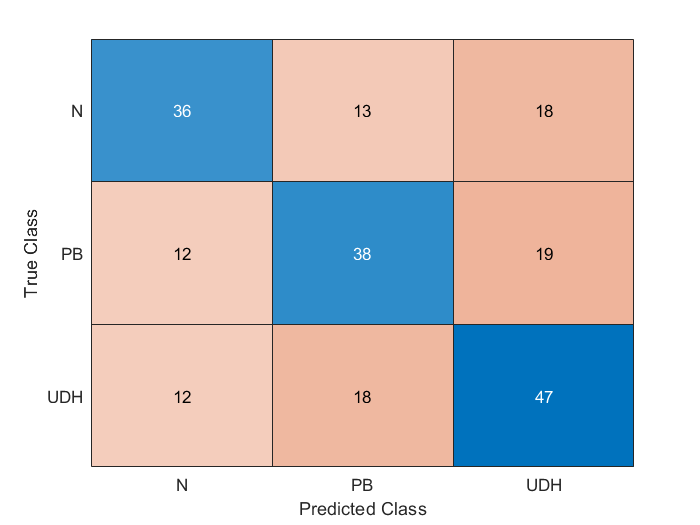

mdlDisAnLoss = kfoldLoss(mdlDisAn, 'Mode', 'Individual');
[yFit,sFit] = kfoldPredict(mdlDisAn);
confusionchart(data_corr.("Tipo de cáncer"),yFit)


mdlDisAn1 = fitcdiscr(data_todo,"Tipo de cáncer","CVPartition",cvpt2, 'DiscrimType','pseudolinear')

mdlDisAn1 =   ClassificationPartitionedModel
    CrossValidatedModel: 'Discriminant'
         PredictorNames: {1×17 cell}
           ResponseName: 'Tipo de cáncer'
        NumObservations: 213
                  KFold: 5
              Partition: [1×1 cvpartition]
             ClassNames: [N    PB    UDH]
         ScoreTransform: 'none'


  Properties, Methods


mdlDisAnLoss1 = kfoldLoss(mdlDisAn1)

mdlDisAnLoss1 =    0.460093896713615


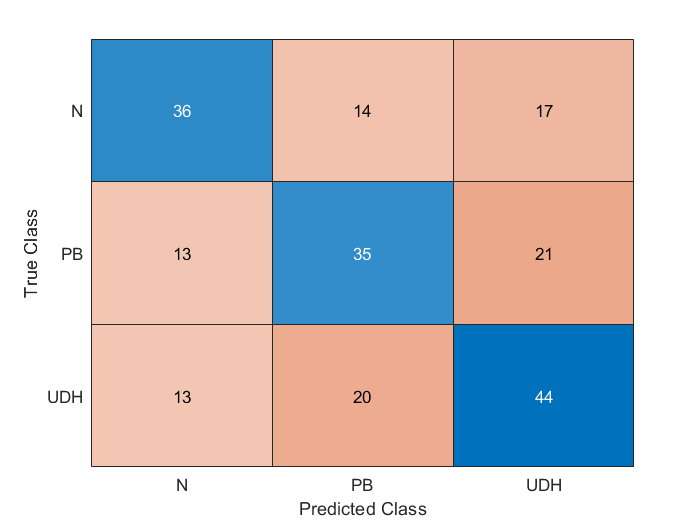

mdlDisAnLoss1 = kfoldLoss(mdlDisAn1, 'Mode', 'Individual');
[yFit,sFit] = kfoldPredict(mdlDisAn1);
confusionchart(data_todo.("Tipo de cáncer"),yFit)


mdlDisAn2 = fitcdiscr(data_todo,"Tipo de cáncer","CVPartition",cvpt2, 'DiscrimType','quadratic')

mdlDisAn2 =   ClassificationPartitionedModel
    CrossValidatedModel: 'Discriminant'
         PredictorNames: {1×17 cell}
           ResponseName: 'Tipo de cáncer'
        NumObservations: 213
                  KFold: 5
              Partition: [1×1 cvpartition]
             ClassNames: [N    PB    UDH]
         ScoreTransform: 'none'


  Properties, Methods


mdlDisAnLoss2 = kfoldLoss(mdlDisAn2)

mdlDisAnLoss2 =    0.464788732394366


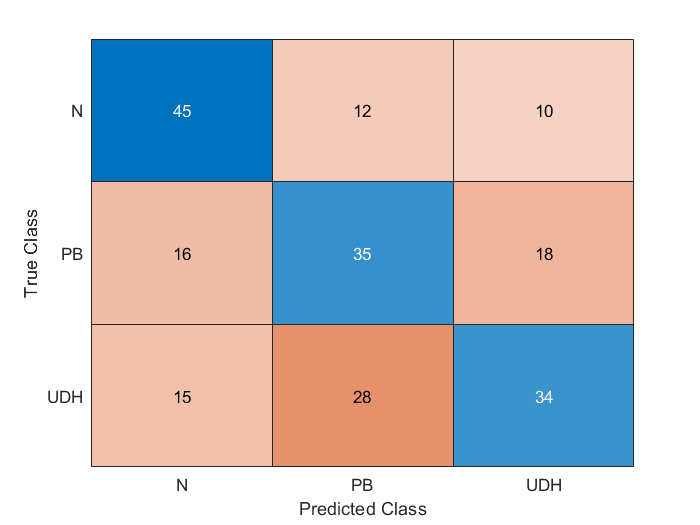

mdlDisAnLoss2 = kfoldLoss(mdlDisAn2, 'Mode', 'Individual');
[yFit,sFit] = kfoldPredict(mdlDisAn2);
confusionchart(data_todo.("Tipo de cáncer"),yFit)

## SVM

%mdlSvm_Opt = fitcecoc(data_corr, "Tipo de cáncer","OptimizeHyperparameters","auto","HyperparameterOptimizationOptions",opt);
mdlSvm = fitcecoc(data_corr, "Tipo de cáncer","CVPartition",cvpt,'Coding','onevsone','Learners','discriminant')

mdlSvm =   ClassificationPartitionedECOC
    CrossValidatedModel: 'ECOC'
         PredictorNames: {1×13 cell}
           ResponseName: 'Tipo de cáncer'
        NumObservations: 213
                  KFold: 5
              Partition: [1×1 cvpartition]
             ClassNames: [N    PB    UDH]
         ScoreTransform: 'none'


  Properties, Methods


mdlSvmLoss = kfoldLoss(mdlSvm)

mdlSvmLoss =    0.399061032863849


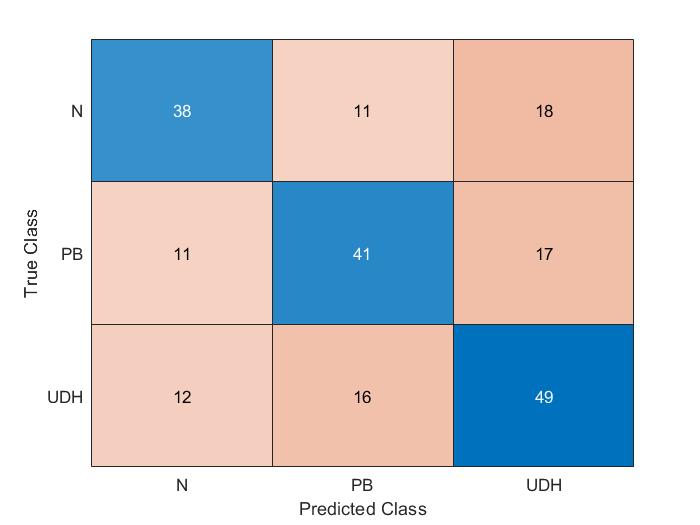

mdlSvmLoss = kfoldLoss(mdlSvm, 'Mode', 'Individual');
[yFit,sFit] = kfoldPredict(mdlSvm);
confusionchart(data_corr.("Tipo de cáncer"),yFit)


mdlSvm1 = fitcecoc(data1, "Tipo de cáncer","CVPartition",cvpt1,'Coding','onevsone','Learners','discriminant')

mdlSvm1 =   ClassificationPartitionedECOC
    CrossValidatedModel: 'ECOC'
         PredictorNames: {1×13 cell}
           ResponseName: 'Tipo de cáncer'
        NumObservations: 213
                  KFold: 5
              Partition: [1×1 cvpartition]
             ClassNames: [N    PB    UDH]
         ScoreTransform: 'none'


  Properties, Methods


mdlSvmLoss1 = kfoldLoss(mdlSvm1)

mdlSvmLoss1 =    0.450704225352112


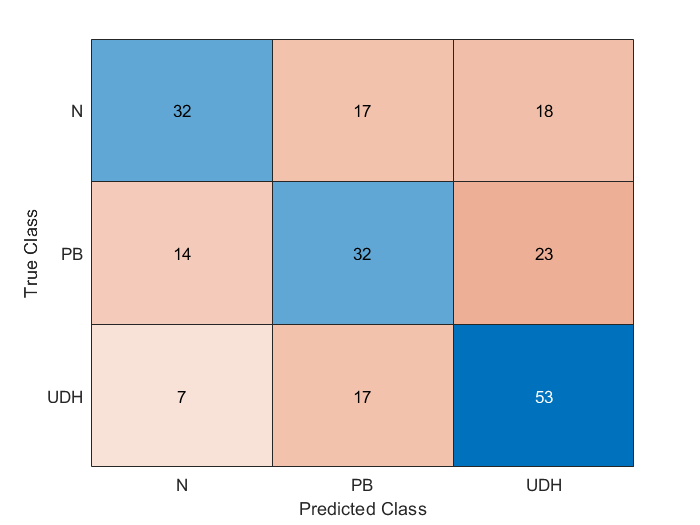

mdlSvmLoss1 = kfoldLoss(mdlSvm1, 'Mode', 'Individual');
[yFit1,sFit1] = kfoldPredict(mdlSvm1);
confusionchart(data1.("Tipo de cáncer"),yFit1)


mdlSvm2 = fitcecoc(data_todo, "Tipo de cáncer","CVPartition",cvpt2,'Coding','onevsone','Learners','discriminant')

mdlSvm2 =   ClassificationPartitionedECOC
    CrossValidatedModel: 'ECOC'
         PredictorNames: {1×17 cell}
           ResponseName: 'Tipo de cáncer'
        NumObservations: 213
                  KFold: 5
              Partition: [1×1 cvpartition]
             ClassNames: [N    PB    UDH]
         ScoreTransform: 'none'


  Properties, Methods


mdlSvmLoss2 = kfoldLoss(mdlSvm2)

mdlSvmLoss2 =    0.417840375586854


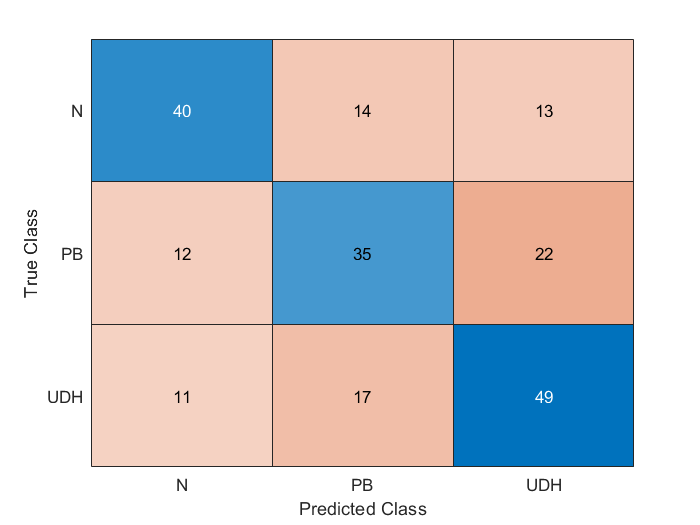

mdlSvmLoss2 = kfoldLoss(mdlSvm2, 'Mode', 'Individual');
[yFit2,sFit2] = kfoldPredict(mdlSvm2);
confusionchart(data_todo.("Tipo de cáncer"),yFit2)

## Ensemble random forest

mdlRF = fitcensemble(data_corr, "Tipo de cáncer","CVPartition",cvpt,"Method","Bag");
mdlRFLoss = kfoldLoss(mdlRF)

mdlRFLoss =    0.436619718309859


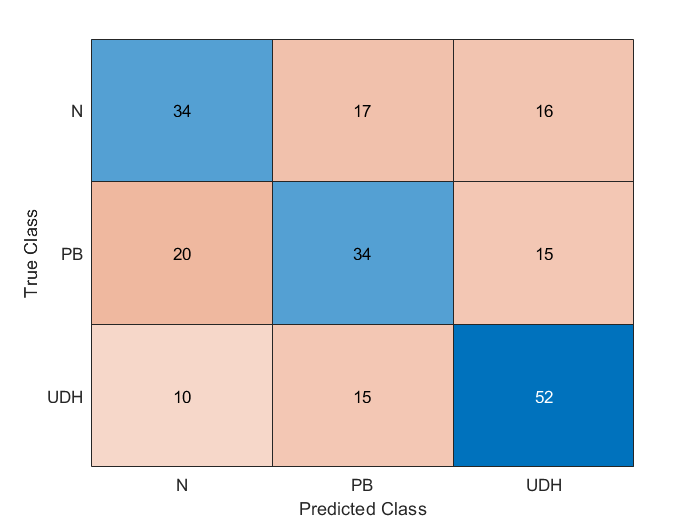

mdlRFLoss = kfoldLoss(mdlRF, 'Mode', 'Individual');
[yFit,sFit] = kfoldPredict(mdlRF);
confusionchart(data_corr.("Tipo de cáncer"),yFit)


mdlRF1 = fitcensemble(data1, "Tipo de cáncer","CVPartition",cvpt1,"Method","Bag");
mdlRFLoss1 = kfoldLoss(mdlRF1)

mdlRFLoss1 =    0.469483568075117


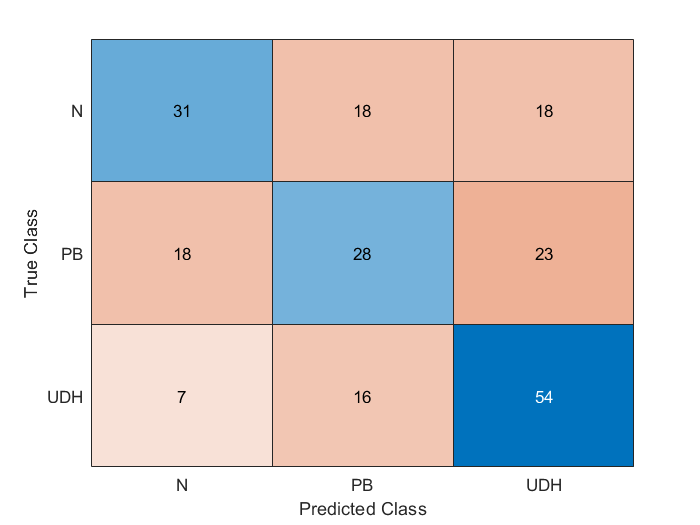

mdlRFLoss1 = kfoldLoss(mdlRF1, 'Mode', 'Individual');
[yFit,sFit] = kfoldPredict(mdlRF1);
confusionchart(data1.("Tipo de cáncer"),yFit)

## Ensemble algo

lrns = {templateKNN("NumNeighbors",3), templateDiscriminant, templateKNN("NumNeighbors",4)}

lrns = 1×3 cell array
    {1×1 classreg.learning.FitTemplate}    {1×1 classreg.learning.FitTemplate}    {1×1 classreg.learning.FitTemplate}


%final_mdl = fitcensemble(data_todo, "Tipo de cáncer","Learners",lnrs)
%lnrs = {templateDiscriminant("delta",3.2158e-05, "gamma",0.00049044 )}
mdlKnnEns = fitcensemble(data_todo, "Tipo de cáncer","Learners",lrns,"CVPartition",cvpt2)

mdlKnnEns =   ClassificationPartitionedEnsemble
    CrossValidatedModel: 'Subspace'
         PredictorNames: {1×17 cell}
           ResponseName: 'Tipo de cáncer'
        NumObservations: 213
                  KFold: 5
              Partition: [1×1 cvpartition]
      NumTrainedPerFold: [300 300 300 300 300]
             ClassNames: [N    PB    UDH]
         ScoreTransform: 'none'


  Properties, Methods


mdlKnnEnsLoss = kfoldLoss(mdlKnnEns)

mdlKnnEnsLoss =    0.535211267605633


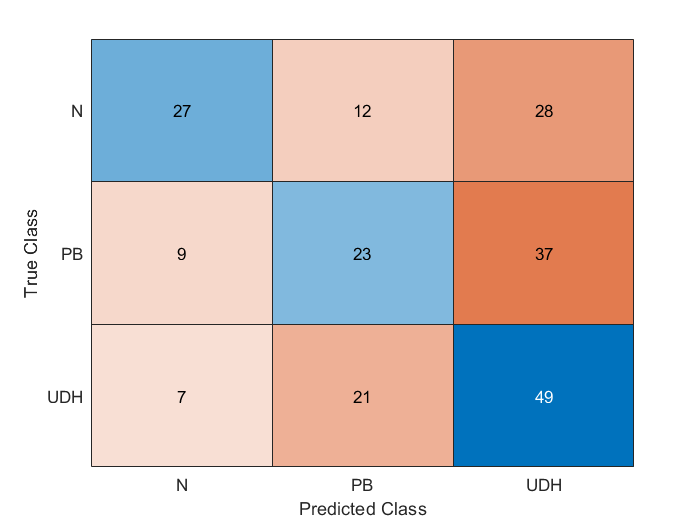

mdlKnnEnsLoss = kfoldLoss(mdlKnnEns, 'Mode', 'Individual');
[yFit,sFit] = kfoldPredict(mdlKnnEns);
confusionchart(data_todo.("Tipo de cáncer"),yFit)

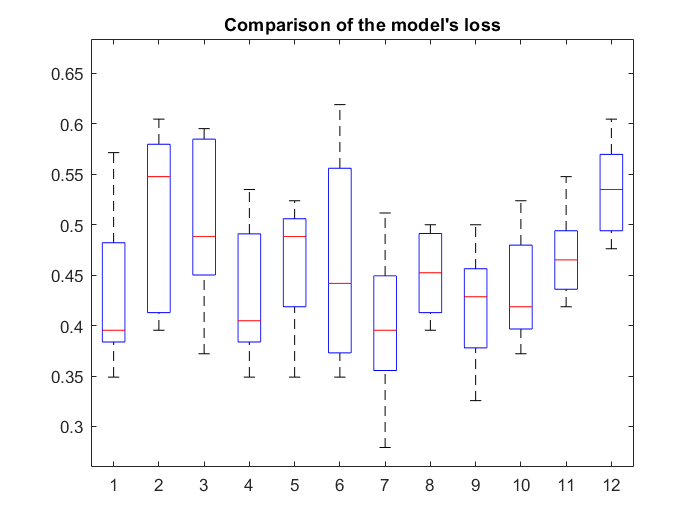

loss_matrix = [[mdlLoss],[mdlTreeLoss], [mdlNBLoss], [mdlDisAnLoss],[mdlDisAnLoss1],[mdlDisAnLoss2],[mdlSvmLoss],[mdlSvmLoss1],[mdlSvmLoss2],[mdlRFLoss],[mdlRFLoss1],[mdlKnnEnsLoss]];
boxplot(loss_matrix)
title("Comparison of the model's loss")

## Cargar tablas de validacion


opts = delimitedTextImportOptions("NumVariables", 24);
% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";
% Specify column names and types
opts.VariableNames = ["Área", "Longitud eje mayor", "Longitud eje menor", "Área convexa","Circularidad", "Perímetro", "Distancia mínima entre núcleos", "Varianza área","Varianza área convexa","Varianza circularidad","Varianza perímetro","Varianza longitud eje mayor","Ratio medio distancia ejes","Porcentaje de núcleos","Varianza de la distancia del eje menor","Compactabilidad de núcleos","Distancia media entre núcleos","Varianza distancia entre núcleos","Varianza del ratio de distancia ejes","Contraste","Correlación", "Homogenidad","Energía","Tipo de cáncer"];
opts.VariableTypes = ["double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","double","categorical"];
% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";
Av = struct2cell(load("0_Nv.mat"));
Av = Av{1,1};
Bv = struct2cell(load("1_PBv.mat"));
Bv = Bv{1,1};
Cv = struct2cell(load("2_UDHv.mat"));
Cv = Cv{1,1};
Taula = [Av; Bv; Cv];
% for i=1:23
%     dataN2(:,i)=array2table(rescale(table2array(dataN1(:,i))));
% end
% data_todo = dataN2;
Taulav = Taula;
for i=1:23
    Taulav(:,i)=array2table(rescale(table2array(Taula(:,i))));
end
TaulaV = processed(Taulav);
TaulaV(:, [1,2,3,4,6,8,10,12,13,22]) = [];

final_mdl = fitcecoc(data_corr, "Tipo de cáncer",'Coding','onevsone','Learners','discriminant');
lrnrs = {templateKNN("NumNeighbors",4), templateDiscriminant, templateKNN("NumNeighbors", 2)}

lrnrs = 1×3 cell array
    {1×1 classreg.learning.FitTemplate}    {1×1 classreg.learning.FitTemplate}    {1×1 classreg.learning.FitTemplate}


%final_mdl = fitcensemble(data_todo, "Tipo de cáncer","Learners",lrnrs)

predictions = predict(final_mdl,TaulaV);
mdlLoss = loss(final_mdl,TaulaV)

mdlLoss =    0.574521615707050


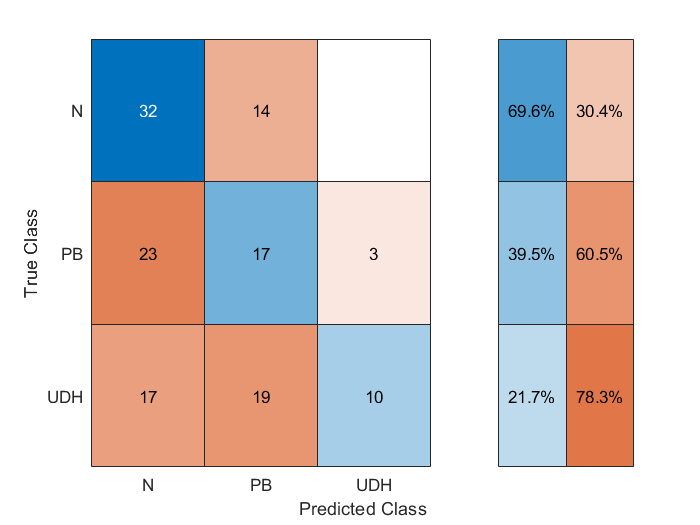

confusionchart(TaulaV.("Tipo de cáncer"),predictions,"RowSummary","row-normalized");

accuracy = sum(TaulaV.("Tipo de cáncer")==predictions)/numel(TaulaV.("Tipo de cáncer"))

accuracy =    0.437037037037037
